% Define a known precision matrix (inverse covariance) with a known sparsity pattern
% 5x5 precision matrix
true_precision = [ 1.0, -0.5,  0.0,  0.0,  0.0;
                  -0.5,  1.0, -0.4,  0.0,  0.0;
                   0.0, -0.4,  1.0, -0.3,  0.0;
                   0.0,  0.0, -0.3,  1.0, -0.2;
                   0.0,  0.0,  0.0, -0.2,  1.0];
               
% Make sure the matrix is symmetric
true_precision = (true_precision + true_precision') / 2;

% Check that true_precision is positive definite
eigvals = eig(true_precision);
if any(eigvals <= 0)
    error('Precision matrix is not positive definite');
end

% Compute the true covariance matrix as the inverse of the precision matrix
true_covariance = inv(true_precision);

% Number of samples to generate
n_samples = 1000;

% Generate data from a multivariate normal distribution
rng(0);  % Set random seed for reproducibility
data = mvnrnd(zeros(1, 5), true_covariance, n_samples);

% Define the sample size
sampleSize = 10;

% Calculate the number of full samples that fit
numFullSamples = floor(size(data,1) / sampleSize);

% Extract only the data that fits into full samples
sampledData = data(1:numFullSamples * sampleSize,:);

% Reshape into samples (optional for viewing as a matrix)
samples = reshape(sampledData', sampleSize,size(data,2), numFullSamples); % Now: [timesteps, variables, segments]


S = cov(data)

% Set regularization parameter for sparsity
lambda = 0.2;

enfoece_psd = false
% Initial guess: use only upper triangular elements
Theta0 = eye(size(S, 1));
% Call the custom Graphical Lasso fitting function with Lasso penalty
Theta_estimated = fitGraphicalLasso( Theta0, S,lambda,enfoece_psd);

% Display the result
disp('Optimal Precision Matrix (Theta):');
disp(Theta_estimated);

% Define a threshold for near-zero values to identify sparsity
threshold = 1e-4;

% Find non-zero structure in true and estimated precision matrices
true_sparsity_pattern = abs(true_precision) > threshold;
estimated_sparsity_pattern = abs(Theta_estimated) > threshold;

% Display the sparsity patterns
figure;
subplot(1, 2, 1);
imagesc(true_sparsity_pattern);
colorbar;
title('True Sparsity Pattern');
xlabel('Variable');
ylabel('Variable');

subplot(1, 2, 2);
imagesc(estimated_sparsity_pattern);
colorbar;
title('Estimated Sparsity Pattern');
xlabel('Variable');
ylabel('Variable');

% Calculate the accuracy of the sparsity pattern
match_rate = sum(sum(true_sparsity_pattern == estimated_sparsity_pattern)) / numel(true_sparsity_pattern);
disp(['Sparsity Pattern Match Rate: ', num2str(match_rate * 100), '%']);

# Comapring LASSO Algorithims

% Define a known precision matrix (inverse covariance) with a known sparsity pattern
lowVariance = false

lowVariance = logical
   0


if lowVariance
    true_precision = [ 1.0, -0.5,  0.0,  0.0,  0.0;
                      -0.5,  1.0, -0.4,  0.0,  0.0;
                       0.0, -0.4,  1.0, -0.3,  0.0;
                       0.0,  0.0, -0.3,  1.0, -0.2;
                       0.0,  0.0,  0.0, -0.2,  1.0];
else
    true_precision = [ 10.0, -1.8, -1.5, -1.2, -0.9;
                  -1.8,  10.0, -1.6, -1.3, -1.0;
                  -1.5, -1.6,  10.0, -1.4, -1.1;
                  -1.2, -1.3, -1.4,  10.0, -1.2;
                  -0.9, -1.0, -1.1, -1.2,  10.0];
end

% Ensure the matrix is symmetric and positive definite
true_precision = (true_precision + true_precision') / 2;
eigvals = eig(true_precision);
if any(eigvals <= 0)
    error('Precision matrix is not positive definite');
end

% Compute the true covariance matrix as the inverse of the precision matrix
true_covariance = inv(true_precision);

% Number of samples to generate
n_samples = 100000;

% Generate data from a multivariate normal distribution
rng(0);  % Set random seed for reproducibility
data = mvnrnd(zeros(1, 5), true_covariance, n_samples);

% Define the sample size and reshape data into segments
% ============================================================================
sampleSize = 10000;  % Define sample size (number of time steps in each segment)
% ============================================================================
[numObservations, numVariables] = size(data);
numFullSamples = floor(numObservations / sampleSize);

% Extract only the data that fits into full samples
sampledData = data(1:numFullSamples * sampleSize, :);

% Reshape into samples with dimensions [sampleSize, numVariables, numFullSamples]
samples = reshape(sampledData, sampleSize, numVariables, numFullSamples);

% Cosntraint to enforce PSD, not required
enforce_psd = false;
% Set regularization parameter for sparsity
lambda = 0.0;

## Graphical Lasso

samplesB = reshape(samples, size(samples,1) * size(samples,3), size(samples,2));
S = cov(samplesB);

% Initial guess: use only upper triangular elements
Theta0 = eye(size(S, 1));
% Call the custom Graphical Lasso fitting function with Lasso penalty
Theta_estimated = fitGraphicalLasso( Theta0, S,lambda,enforce_psd);

% Display the result
disp('GL: Optimal Precision Matrix (Theta):');

GL: Optimal Precision Matrix (Theta):


disp(Theta_estimated);

   10.0384   -1.7849   -1.4399   -1.2414   -0.9014
   -1.7849    9.9452   -1.5812   -1.3182   -0.9126
   -1.4399   -1.5812   10.0037   -1.4278   -1.1510
   -1.2414   -1.3182   -1.4278   10.0449   -1.2237
   -0.9014   -0.9126   -1.1510   -1.2237   10.0059



## Time Varying Graphical Lasso


% Calculate the empirical covariance matrices for each segment
S = zeros(numVariables, numVariables, numFullSamples);  % Initialize covariance matrix storage
for t = 1:numFullSamples
    S(:, :, t) = cov(squeeze(samples(:, :, t)));  % Calculate covariance for each segment
end


% Set initial precision matrices and regularization parameter
Theta0 = repmat(eye(size(S, 1)), 1, 1, numFullSamples);  % Initial guess as identity matrices
enforce_psd = false;  % Enforce positive semidefiniteness

% Call the fitTimeVaryingGraphicalLasso function
Theta_estimated_TVGL = fitTimeVaryingGraphicalLasso(Theta0, S, lambda, numFullSamples,enforce_psd);

% Display results
disp('TVGL (No transion Penalty): Estimated precision matrices:');

TVGL (No transion Penalty): Estimated precision matrices:


disp(Theta_estimated_TVGL);


(:,:,1) =

    8.9221   -0.0553   -0.0012   -0.1000   -0.0038
   -0.0553    8.9521    0.0292    0.1186    0.0421
   -0.0012    0.0292    8.7819    0.1804    0.0191
   -0.1000    0.1186    0.1804    9.0236   -0.1065
   -0.0038    0.0421    0.0191   -0.1065    8.5675


(:,:,2) =

    8.6995   -0.0010    0.0407   -0.0145   -0.0271
   -0.0010    8.8007   -0.0535   -0.1038    0.0212
    0.0407   -0.0535    9.0645   -0.0395   -0.1543
   -0.0145   -0.1038   -0.0395    8.8464   -0.1371
   -0.0271    0.0212   -0.1543   -0.1371    8.6393


(:,:,3) =

    8.5458   -0.0691    0.0407    0.1803   -0.0053
   -0.0691    8.7103   -0.1869    0.1080   -0.0617
    0.0407   -0.1869    8.5010    0.0242    0.0316
    0.1803    0.1080    0.0242    8.7178    0.0292
   -0.0053   -0.0617    0.0316    0.0292    8.6786


(:,:,4) =

    8.6855    0.0996   -0.1054   -0.0359   -0.0618
    0.0996    8.8977   -0.1381   -0.0460   -0.0042
   -0.1054   -0.1381    8.5965   -0.2282   -0.0196
   -0.0359   -0.0460   -0.2282 

## Time Varying Graphical Lasso with Transition Penalty

beta = 0.4;
% Initial guess: use only upper triangular elements
Theta0 = repmat(eye(size(S,1)), 1, 1, numFullSamples); 
% Call the custom Graphical Lasso fitting function with Lasso penalty
Theta_estimated_TVGL_TP= fitTimeVaryingGraphicalLassoSmoothing(Theta0, S, lambda, beta, numFullSamples, enforce_psd);

% Display the result


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


disp('TVGL with Transition Penalty: Optimal Precision Matrix (Theta):');
disp(Theta_estimated_TVGL_TP);


TVGL with Transition Penalty: Optimal Precision Matrix (Theta):


% Add temporal smoothing penalty between consecutive precision matrices


(:,:,1) =

    8.7768   -0.0226    0.0066   -0.0287   -0.0047
   -0.0226    8.8625   -0.0483    0.0414    0.0077
    0.0066   -0.0483    8.7991    0.0256   -0.0207
   -0.0287    0.0414    0.0256    8.8896   -0.0453
   -0.0047    0.0077   -0.0207   -0.0453    8.6306


(:,:,2) =

    8.7538   -0.0177    0.0075   -0.0178   -0.0047
   -0.0177    8.8487   -0.0603    0.0297    0.0019
    0.0075   -0.0603    8.8024    0.0012   -0.0276
   -0.0178    0.0297    0.0012    8.8698   -0.0352
   -0.0047    0.0019   -0.0276   -0.0352    8.6415


(:,:,3) =

    8.7398   -0.0156    0.0033   -0.0075   -0.0011
   -0.0156    8.8427   -0.0736    0.0394   -0.0066
    0.0033   -0.0736    8.7651   -0.0163   -0.0143
   -0.0075    0.0394   -0.0163    8.8543   -0.0085
   -0.0011   -0.0066   -0.0143   -0.0085    8.6535


(:,:,4) =

    8.7590   -0.0041   -0.0072   -0.0287    0.0035
   -0.0041    8.8591   -0.0672    0.0373   -0.0061
   -0.0072   -0.0672    8.7727   -0.0407   -0.0085
   -0.0287    0.0373   -0.0407 

f = zeros(1,size(Theta_estimated_TVGL,3)-1);
for t = 2:1:size(Theta_estimated_TVGL,3)
    diff_matrix = Theta_estimated_TVGL(:, :, t) - Theta_estimated_TVGL(:, :, t-1);
    p = norm(diff_matrix, 'fro')^2; % Normalized penalty
    f(t) = p;
end

g = zeros(1,size(Theta_estimated_TVGL_TP,3)-1);
for t = 2:1:size(Theta_estimated_TVGL_TP,3)
    diff_matrix = Theta_estimated_TVGL_TP(:, :, t) - Theta_estimated_TVGL_TP(:, :, t-1);
    q = norm(diff_matrix, 'fro')^2; % Normalized penalty
    g(t) = q;
end

figure
plot(f)
hold on
plot(g)
hold off

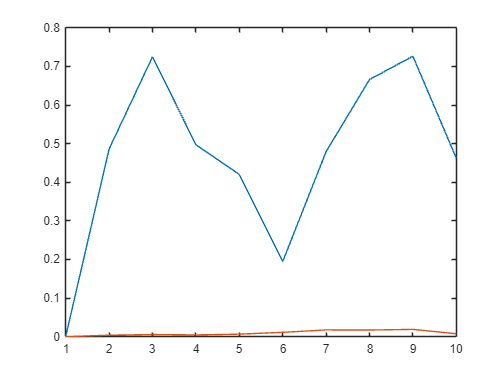


figure


Betas = 0:0.1:1;
g = zeros(length(Betas),size(Theta_estimated_TVGL_TP,3)-1);
for i = 1:1:length(Betas)
    beta = Betas(i);
    % Initial guess: use only upper triangular elements
    Theta0 = repmat(eye(size(S,1)), 1, 1, numFullSamples); 
    % Call the custom Graphical Lasso fitting function with Lasso penalty
    Theta_estimated_TVGL_TP= fitTimeVaryingGraphicalLassoSmoothing(Theta0, S, lambda, beta, numFullSamples, enforce_psd);
    
   
    for t = 2:1:size(Theta_estimated_TVGL_TP,3)
        diff_matrix = Theta_estimated_TVGL_TP(:, :, t) - Theta_estimated_TVGL_TP(:, :, t-1);
        q = norm(diff_matrix, 'fro')^2; % Normalized penalty
        g(i,t) = q;
    end

end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

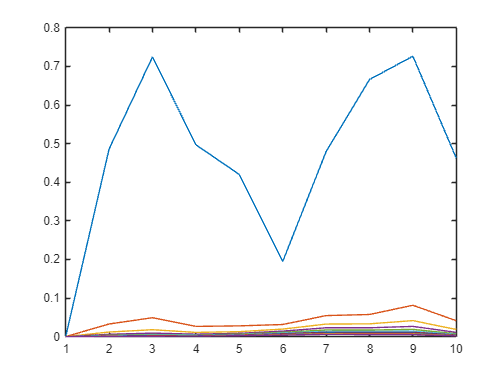

plot(g')